% sim = coppeliaRobot();

## Set up

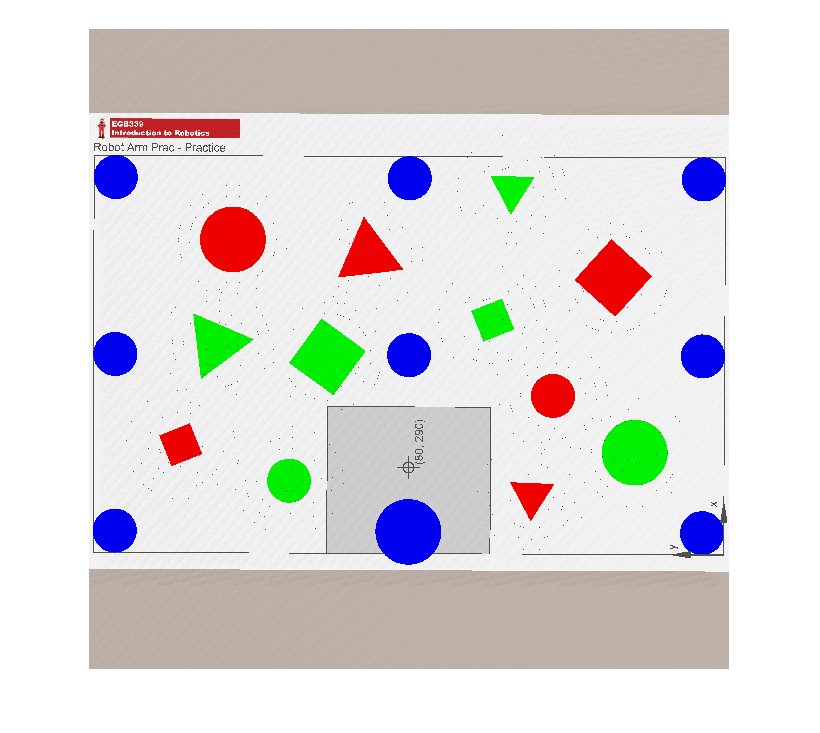

% q = getJointPositions(sim)
clear All; close all;

q = [0 -24 -21 45 0]; % Perfect for top view picture
q0 = [0 0 0 0 0];
setJointPositions(sim, q);
% % Capture image
pause(3);
image = getImage(sim);
imshow(image);

% imwrite(image, 'capture.jpg');

% Set cylinders
init_xy = [275 288 335; 327 452 196];
dest_xy = [300 400; 300 200; 150 150];

setCylinderPosition(sim, init_xy);

xy =     0.2750    0.2880    0.3350
    0.3270    0.4520    0.1960


Index in position 1 exceeds array bounds (must not exceed 2).

Error in coppeliaRobot/setCylinderPosition (line 153)
               obj.vrep.simxSetObjectPosition(obj.clientID,obj.handles.cylinderHandle(i),-1,[xy(i,1:2) 0.7226],obj.vrep.simx_opmode_oneshot );

% ----------------------------------------
% Inverse Kinematics
% Robot specs
L1 = 138;
L2 = 135;
L3 = 147;
L4 = 60; L5 = 80; L6 = 100; 

% Robot position on workspace
xRobot = 80; yRobot = 290;

% Aim for cylinder 1 
x = 275; y = 327; z = 50; % cylinder height/ in milimeter

phi = 0;    % angle of the vacuum gripper
phi0 = pi/2 - phi;

% y-yRobot
% x-xRobot
% y-yRobot/x-xRobot
theta1 = atan((y-yRobot)/(x-xRobot))
rad2deg(theta1) 

% distance_to_target_xy_plane
distance = sqrt((x-xRobot)^2 + (y-yRobot)^2) 
omega = atan(L5/L4)
ww = pi/2 - omega - phi; % fork-like icon
ww0 = omega + phi;

Lh = sin(ww)*L6
Lv = cos(ww)*L6
% pg30lec10
r = sqrt((distance - Lh)^2 + (z - L1+Lv)^2)
si = atan2((z - L1+Lv),(distance - Lh)) % s angle sign
L2
L3
r
beta = acos((L2^2 + L3^2 - r^2)/(2*L2*L3))
beta * 180
alpha = asin(sin(beta)/r*L3)

theta2 = pi/2 - alpha - si                                 %
theta3 = pi/2 - beta   % Robot angle is already added 90 degrees, therefore minus it off
theta4 = pi/2 - theta3 - theta2 + (pi/2 - phi0);            %
theta4 = - theta3 - theta2  % testing our way

q_new = rad2deg([theta1 theta2 theta3 theta4 0])
setJointPositions(sim, rad2deg([theta1 theta2 theta3 theta4 0]));
% setJointPositions(sim, q_new);

% Suck
setSuctionCup(sim , 1)



## Back to origin

setJointPositions(sim, q0);

## Reach to destination

done = reach(sim, dest_xy(2,1), dest_xy(2,2))

## Drop

setSuctionCup(sim , 0)

## Origin

setJointPositions(sim, q0);

## Loop with given init_xy and dest_xy

setJointPositions(sim, q0);
for i = 1:3
    q_new = reach(init_xy(i,1), init_xy(i,2), sim);
    setSuctionCup(sim , 1);
    
    % origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 10);
    for q=q_mid'
        setJointPositions(sim, q);
        pause(0.01);
    end
    
    reach(dest_xy(i,1), dest_xy(i,2), sim);
    setSuctionCup(sim , 0);
    
    % origin
    q_current = getJointPositions(sim);
    q_mid = jtraj(q_current, q0, 20);
    for q=q_mid'
        setJointPositions(sim, q);
        pause(0.01);
    end
end

## Process capture image

% replace image file with realtime image later
capture = double(imread("capture.jpg"));
% Zero the text part
plainImage = capture;
plainImage(1:122,:,:) = 0;
% plainImage = plainSpace(:,1:3015,:);  %double(plainspace(60:4619,129:2995,:));
% imshow(plainImage)

% Get colour plains
red = plainImage(:,:,1);
green = plainImage(:,:,2);
blue = plainImage(:,:,3);

% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));
% figure; imshow(blueCircles); title("blueCircles");

% Get blue shapes' stats
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
hold off

% HOMOGRAPHY

% Store data
blueCentroids = cat(1,blueStats.Centroid);
blueAreas = cat(1,blueStats.Area);

% Left bottom circle = start circle

startCircleCentroid = [min(blueCentroids(:,1))+10 max(blueCentroids(:,2))-10]

i = [blueCentroids(:,1) < startCircleCentroid(1),  blueCentroids(:,2) > startCircleCentroid(2)]
i = i(:,1)+i(:,2)
startPosition = find(i==2)

% Clone variable
centroidsNew = blueCentroids;
% Remove the largest circle
centroidsNew(startPosition,:) = [];
% 3rd column: Calculate and add distanceFromLargest circle
distanceFromLargest = [centroidsNew, sqrt(abs(centroidsNew(:,1)-blueCentroids(startPosition,1)).^2 + abs(centroidsNew(:,2)-blueCentroids(startPosition,2)).^2)];
% 4th column: Add sum of coordinates
distanceFromLargest = [distanceFromLargest, distanceFromLargest(:,1)+distanceFromLargest(:,2)];
% Sort in the ascending order of distanceFromLargest
distanceSorted = sortrows( distanceFromLargest, 3);
sorted3 = sortrows( distanceSorted(1:3,:), 4);
sorted5 = sortrows( distanceSorted(4:8,:), 4);
% Now put them in P, order is right as required
P = [blueCentroids(startPosition,1:2)' sorted3(:,1:2)' sorted5(:,1:2)' ; ones(1,9) ]
% The Euclidean workspace coordinates of the markers
Q = [ 20 182.5 182.5 20 345 345 345 182.5 20;  560 560 290 290 560 290 20 20 20;  ones(1,9) ]
H = simple_homography(P,Q)
aShapeInImage =  [92; 417 ; 1]
aShapeOnWorld = H * aShapeInImage
